# Chapter 7 Boundary Value Problems Examples

#### Example 7.2

% Define ODE function
f = @(t, y) [y(2) ; y(1) + y(2)];

% Define BVP parameters
tspan = [0, 1];     % boundaries of the t domain
bvals = [0, 2];     % boundary values
h = 0.2;            % step length
s = [1, 2, 1.5];    % guess values

% Calculate the solution to the IVP for the different guess values
[t, y1] = euler(f, tspan, [bvals(1), s(1)], h);
[t, y2] = euler(f, tspan, [bvals(1), s(2)], h);
[t, y3] = euler(f, tspan, [bvals(1), s(3)], h);

% Print table of solutions
for i = 1 : 1
    fprintf("s = %0.2f", y1(1,2))
    fprintf("|  $t$  |  $y_1$   |  $y_2$   |")
    fprintf("|:-----:|:--------:|:--------:|")
    for n = 1 : length(t)
        fprintf("| %5.2f | %7.6f | %7.6f |\n", t(n), y1(n,1), y1(n,2))
    end
end

s = 1.00

|  $t$  |  $y_1$   |  $y_2$   |

|:-----:|:--------:|:--------:|

|  0.00 | 0.000000 | 1.000000 |
|  0.20 | 0.200000 | 1.200000 |
|  0.40 | 0.440000 | 1.480000 |
|  0.60 | 0.736000 | 1.864000 |
|  0.80 | 1.108800 | 2.384000 |
|  1.00 | 1.585600 | 3.082560 |


for i = 1 : 1
    fprintf("s = %0.2f", y1(1,2))
    fprintf("|  $t$  |  $y_1$   |  $y_2$   |")
    fprintf("|:-----:|:--------:|:--------:|")
    for n = 1 : length(t)
        fprintf("| %5.2f | %7.6f | %7.6f |\n", t(n), y2(n,1), y2(n,2))
    end
end

s = 1.00

|  $t$  |  $y_1$   |  $y_2$   |

|:-----:|:--------:|:--------:|

|  0.00 | 0.000000 | 2.000000 |
|  0.20 | 0.400000 | 2.400000 |
|  0.40 | 0.880000 | 2.960000 |
|  0.60 | 1.472000 | 3.728000 |
|  0.80 | 2.217600 | 4.768000 |
|  1.00 | 3.171200 | 6.165120 |


for i = 1 : 1
    fprintf("s = %0.2f", y1(1,2))
    fprintf("|  $t$  |  $y_1$   |  $y_2$   |")
    fprintf("|:-----:|:--------:|:--------:|")
    for n = 1 : length(t)
        fprintf("| %5.2f | %7.6f | %7.6f |\n", t(n), y3(n,1), y3(n,2))
    end
end

s = 1.00

|  $t$  |  $y_1$   |  $y_2$   |

|:-----:|:--------:|:--------:|

|  0.00 | 0.000000 | 1.500000 |
|  0.20 | 0.300000 | 1.800000 |
|  0.40 | 0.660000 | 2.220000 |
|  0.60 | 1.104000 | 2.796000 |
|  0.80 | 1.663200 | 3.576000 |
|  1.00 | 2.378400 | 4.623840 |


#### Example 7.3

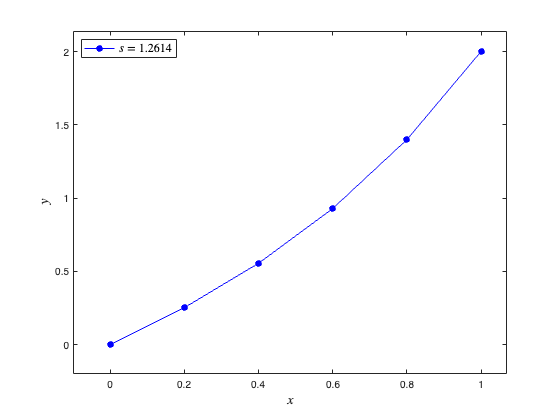

% Define ODE function
f = @(t, y) [y(2) ; y(1) + y(2)];

% Define BVP parameters
tspan = [0, 1];     % boundaries of the t domain
bvals = [0, 2];     % boundary values
h = 0.2;            % step length

% Solve BVP using the shooting method
[t, y] = solve_bvp(f, tspan, bvals, h, @euler, 1e-4);

% Plot solution
plot(t, y(:,1), "b-o", MarkerFaceColor="b")
xlabel("$x$", FontSize=14, Interpreter="latex")
ylabel("$y$", FontSize=14, Interpreter="latex")
legend(sprintf("$s = %0.4f$", y(1,2)), Fontsize=12, Interpreter="latex", Location="northwest")
axis padded

#### Example 7.4

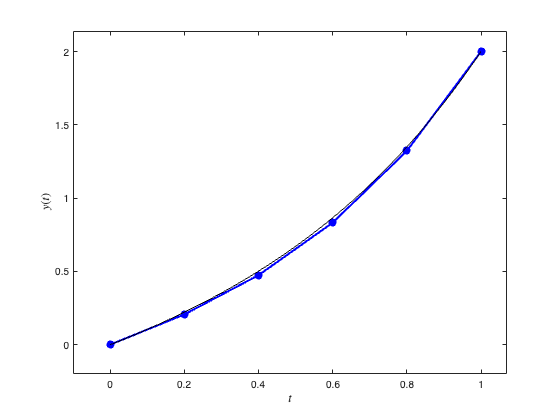

exact = @(t, y) 2 * exp((1 - sqrt(5)) .* (t - 1) / 2) .* (exp(sqrt(5) * t) - 1) / (exp(sqrt(5)) - 1);

% Define BVP parameters
tspan = [0, 1];
bvals = [0, 2];
h = 0.2;

% Define linear system
n = floor((tspan(2) - tspan(1)) / h) + 1;
t = (tspan(1) : h : tspan(2));
A = eye(n);
b = zeros(n, 1);
b(1) = bvals(1);
b(n) = bvals(2);
for i = 2 : n - 1
    A(i, i-1) = 1;
    A(i, i) = h - h ^ 2 - 2;
    A(i, i+1) = 1 - h;
end

% Solve linear system
y = A \ b;

% Calculate exact solution
texact = linspace(tspan(1), tspan(2), 100);
yexact = exact(texact);

% Plot solution
clf
plot(t, y, 'b-o', LineWidth=2, MarkerFaceColor='b')
hold on
plot(texact, yexact, 'k')
hold off
xlabel('$t$', Interpreter='latex', FontSize=12)
ylabel('$y(t)$', Interpreter='latex', FontSize=12)
axis padded

## Functions

#### Euler method

function [t, y] = euler(f, tspan, y0, h)

nsteps = floor((tspan(2) - tspan(1)) / h);
N = length(y0);
t = zeros(1, nsteps + 1);
y = zeros(N, nsteps + 1);
t(1) = tspan(1);
y(:, 1) = y0;

for n = 1 : length(t) - 1
    y(:, n+1) = y(:, n) + h * f(t(n), y(:, n));
    t(n+1) = t(n) + h;
end

y = y';

end

#### Shooting method

function [t, y] = solve_bvp(f, tspan, bvals, h, solver, tol)

s = 1;
sold = 2;
gold = 1;
for i = 1 : 10
    [t, y] = solver(f, tspan, [bvals(1), s], h);
    g = bvals(2) - y(end, 1);
    snew = s - g * (s - sold) / (g - gold);
    sold = s;
    s = snew;
    gold = g;
    if abs(s - sold) < tol
        break
    end
end

end